clc
clear
warning('off','all')
% Dados:
% IEEE 14 barras
% [       NUM    TIPO    V        TETA     PG    QG      PD         QD       GSH    BSH ]
barras = [
            1   2   1.060 0.0  232.4 -16.9  0.0     0.0     0.0    0.0 0 0
            2   1   1.045 0.0  40.0  42.4  21.70  12.70    0.0    0.0 -40  50
            3   1   1.010 0.0  0.0  23.4  94.20  19.00    0.0    0.0 0    40
            4   0   1.000 0.0  0.0   0.0  47.80   -3.90   0.0    0.0 0    0
            5   0   1.000 0.0  0.0   0.0  7.60   1.600    0.0    0.0 0    0
            6   1   1.070 0.0  0.0   12.2  11.20  7.500    0.0    0.0 -6   24
            7   0   1.000 0.0  0.0   0.0   0.0    0.0     0.0    0.0 0    0
            8   1   1.090 0.0  0.0   17.4   0.0    0.0     0.0    0.0 -6   24
            9   0   1.000 0.0  0.0   0.0  29.50   16.60   0.0   19.0 0    0
            10  0   1.000 0.0  0.0   0.0   9.00   5.800   0.0    0.0 0    0
            11  0   1.000 0.0  0.0   0.0   3.50   1.800   0.0    0.0 0    0
            12  0   1.000 0.0  0.0   0.0   6.10   1.600   0.0    0.0 0    0
            13  0   1.000 0.0  0.0   0.0   13.50  5.800   0.0    0.0 0    0
            14  0   1.000 0.0  0.0   0.0   14.90  5.000   0.0    0.0 0    0 ];

%            [FR    TO         R          X      BSHtotal   Tap  ]
linhas = [
1	2	0.01938  0.05917	0.05280    0    	
1	5	0.05403  0.22304	0.04920    0    	
2	3	0.04699  0.19797	0.04380    0   
2	4	0.05811  0.17632	0.03400    0    	
2	5	0.05695  0.17388	0.03460    0      
3	4	0.06701  0.17103	0.01280    0    	
4	5	0.01335  0.04211	0          0    	
4	7	0.0      0.20912	0  	    0.978   
4	9	0.0      0.55618	0  	    0.969   
5	6	0.0      0.25202	0  	    0.932  
6	11	0.09498  0.19890	0          0    	
6	12	0.12291  0.25581	0          0    	
6	13	0.06615  0.13027	0          0    	
7	8	0.0      0.17615  	0          0      	
7	9	0.0      0.11001	0          0    	
9	10	0.03181  0.08450	0  	       0      
9	14	0.12711  0.27038	0          0    	
10	11	0.08205  0.19207	0          0    	
12	13	0.22092  0.19988	0          0  	
13	14	0.17093  0.34802	0          0     	 ];


Custo = [1 1 2 4 4];
MaxP  = [250 40 15 15 15];
MaxQ  = [50  50  50 50 50];
MinP  = [0 0 0 0 0];
MinQ  = [-50 -50 -50 -50 -50];

Ref= 1;
% ========================
% Leitura dos dados de entrada

[NumBarras,NumBCol] = size(barras);
[NumLinhas,NumLCol] = size(linhas);

% Linhas
% Init das variaveis
de = zeros(NumLinhas,1);
para = zeros(NumLinhas,1);
R = zeros(NumLinhas,1);
X = zeros(NumLinhas,1);
B = zeros(NumLinhas,1);
Tap = zeros(NumLinhas,1);

for i=1:NumLinhas
    de(i) = linhas(i,1);
    para(i) = linhas(i,2);
    R(i) = linhas(i,3);
    X(i) = linhas(i,4);
    B(i) = 1/X(i);
    Tap(i) = linhas(i,6);
end

% Desconsiderando taps
Tap = ones(NumLinhas,1);

% Barras
% Init das variaveis
Tipo = zeros(NumBarras,1);
V = zeros(NumBarras,1);
Teta = zeros(NumBarras,1);
Pg = zeros(NumBarras,1);
Qg = zeros(NumBarras,1);
Pd = zeros(NumBarras,1);
Qd = zeros(NumBarras,1);
Gsh = zeros(NumBarras,1);
Bsh = zeros(NumBarras,1);

for i=1:NumBarras
    Tipo(i) = barras(i,2);
    V(i) = barras(i,3);
    Teta(i) = barras(i,4);
    Pg(i) = barras(i,5);
    Qg(i) = barras(i,6);
    Pd(i) = barras(i,7);
    Qd(i) = barras(i,8);
    Gsh(i) = barras(i,9);
    Bsh(i) = barras(i,10);
end

% Potencias em PU
Pg = Pg/100;
Qg = Qg/100;
Pd = Pd/100;
Qd = Qd/100;



% ========================
% Matriz B_linha

B_linha = zeros(NumBarras,NumBarras);

for i=1:NumLinhas
    K = de(i);
    M = para(i);
    B_linha(K,K) = B_linha(K,K) + B(i)/(Tap(i)^2); % diagonal principal considerando tap  
    B_linha(M,M) = B_linha(M,M) + B(i); % diagonal principal
    B_linha(K,M) = B_linha(K,M) - B(i)/Tap(i); % Fora da diagonal principal
    B_linha(M,K) = B_linha(M,K) - B(i)/Tap(i); % Fora da diagonal principal
end

% ========================
% Fluxo de potencia linearizado


B_REF = Ref;
B_linha(B_REF,B_REF) = 10^20; % Infinito
Teta=  B_linha\(-Pd+Pg); % inv

Pkm = zeros(NumLinhas,1);

for i=1:NumLinhas
    K = de(i);
    M = para(i);
    Pkm(i) = (Teta(K)-Teta(M))*B(i)/Tap(i); % Pkm = Pk - Pm
end

% Variaveis de saida
disp('Fluxo de potencia linearizado - IEEE 14 Barras -  Pd = 100%')

Fluxo de potencia linearizado - IEEE 14 Barras -  Pd = 100%


disp('Teta: ')

Teta: 


disp(Teta)

    0.0000
   -0.0875
   -0.2262
   -0.1849
   -0.1586
   -0.2647
   -0.2455
   -0.2455
   -0.2774
   -0.2826
   -0.2772
   -0.2840
   -0.2869
   -0.3042



disp('Pkm: ')

Pkm: 


disp(Pkm)

    1.4788
    0.7112
    0.7005
    0.5523
    0.4090
   -0.2415
   -0.6234
    0.2899
    0.1663
    0.4208
    0.0630
    0.0755
    0.1703
   -0.0000
    0.2899
    0.0620
    0.0992
   -0.0280
    0.0145
    0.0498




% Analisando para Pd a 80% ============================
Pd1 = Pd*0.8;
Teta1=  B_linha\(-Pd1+Pg);

Pkm1 = zeros(NumLinhas,1);

for i=1:NumLinhas
    K = de(i);
    M = para(i);
    Pkm1(i) = (Teta1(K)-Teta1(M))*B(i)/Tap(i); % Pkm = Pk - Pm
end

% Variaveis de saida
disp('Fluxo de potencia linearizado - IEEE 14 Barras -  Pd = 80%')

Fluxo de potencia linearizado - IEEE 14 Barras -  Pd = 80%


disp('Teta: ')

Teta: 


disp(Teta1)

    0.0000
   -0.0660
   -0.1774
   -0.1447
   -0.1240
   -0.2088
   -0.1933
   -0.1933
   -0.2188
   -0.2230
   -0.2188
   -0.2242
   -0.2265
   -0.2403



disp('Pkm: ')

Pkm: 


disp(Pkm1)

    1.1160
    0.5560
    0.5626
    0.4464
    0.3334
   -0.1910
   -0.4923
    0.2321
    0.1332
    0.3363
    0.0502
    0.0603
    0.1362
         0
    0.2321
    0.0498
    0.0795
   -0.0222
    0.0115
    0.0397





% Analisando para Pd a 120% ============================
Pd2 = Pd*1.2;
Teta2=  B_linha\(-Pd2+Pg);

Pkm2 = zeros(NumLinhas,1);

for i=1:NumLinhas
    K = de(i);
    M = para(i);
    Pkm2(i) = (Teta2(K)-Teta2(M))*B(i)/Tap(i); % Pkm = Pk - Pm
end

% Variaveis de saida
disp('Fluxo de potencia linearizado - IEEE 14 Barras -  Pd = 120%')

Fluxo de potencia linearizado - IEEE 14 Barras -  Pd = 120%


disp('Teta: ')

Teta: 


disp(Teta2)

   -0.0000
   -0.1090
   -0.2749
   -0.2250
   -0.1932
   -0.3206
   -0.2977
   -0.2977
   -0.3359
   -0.3422
   -0.3357
   -0.3438
   -0.3472
   -0.3681



disp('Pkm: ')

Pkm: 


disp(Pkm2)

    1.8416
    0.8664
    0.8384
    0.6581
    0.4847
   -0.2920
   -0.7545
    0.3476
    0.1994
    0.5054
    0.0759
    0.0906
    0.2045
   -0.0000
    0.3476
    0.0741
    0.1189
   -0.0339
    0.0174
    0.0599



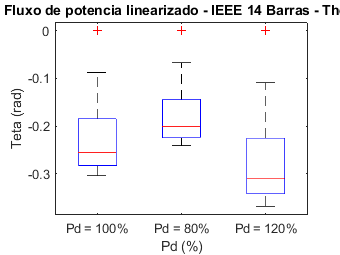


% Box Plot
figure(1)
boxplot([Teta Teta1 Teta2],'Labels',{'Pd = 100%','Pd = 80%','Pd = 120%'})
title('Fluxo de potencia linearizado - IEEE 14 Barras - Theta')
ylabel('Teta (rad)')
xlabel('Pd (%)')

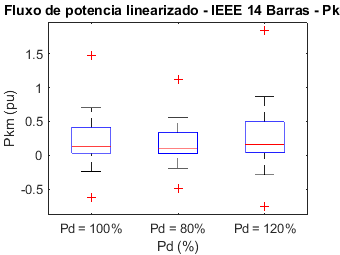


% Box Plot Pkm
figure(2)
boxplot([Pkm Pkm1 Pkm2],'Labels',{'Pd = 100%','Pd = 80%','Pd = 120%'})
title('Fluxo de potencia linearizado - IEEE 14 Barras - Pkm')
ylabel('Pkm (pu)')
xlabel('Pd (%)')

## IEEE 33 Barras

% Dados:


% [       NUM    TIPO    V        TETA     PG    QG      PD         QD       GSH    BSH ]
barras = [           
            1      0     1.0000  0.0000    0      0      100.0      60.0     0.0    0.0;
            2      0     1.0000  0.0000    0      0       90.0      40.0     0.0    0.0;
            3      0     1.0000  0.0000    0      0      120.0      80.0     0.0    0.0;
            4      0     1.0000  0.0000    0      0       60.0      30.0     0.0    0.0;
            5      0     1.0000  0.0000    0      0       60.0      20.0     0.0    0.0;
            6      0     1.0000  0.0000    0      0      200.0     100.0     0.0    0.0;
            7      0     1.0000  0.0000    0      0      200.0     100.0     0.0    0.0;
            8      0     1.0000  0.0000    0      0       60.0      20.0     0.0    0.0;
            9      0     1.0000  0.0000    0      0       60.0      20.0     0.0    0.0;
           10      0     1.0000  0.0000    0      0       45.0      30.0     0.0    0.0;
           11      0     1.0000  0.0000    0      0       60.0      35.0     0.0    0.0;
           12      0     1.0000  0.0000    0      0       60.0      35.0     0.0    0.0;
           13      0     1.0000  0.0000    0      0      120.0      80.0     0.0    0.0;
           14      0     1.0000  0.0000    0      0       60.0      10.0     0.0    0.0;
           15      0     1.0000  0.0000    0      0       60.0      20.0     0.0    0.0;
           16      0     1.0000  0.0000    0      0       60.0      20.0     0.0    0.0;    
           17      0     1.0000  0.0000    0      0       90.0      40.0     0.0    0.0;
           18      0     1.0000  0.0000    0      0       90.0      40.0     0.0    0.0;
           19      0     1.0000  0.0000    0      0       90.0      40.0     0.0    0.0;
           20      0     1.0000  0.0000    0      0       90.0      40.0     0.0    0.0;
           21      0     1.0000  0.0000    0      0       90.0      40.0     0.0    0.0;
           22      0     1.0500  0.0000    0      0       90.0      50.0     0.0    0.0;
           23      0     1.0000  0.0000    0      0      420.0     200.0     0.0    0.0;
           24      0     1.0000  0.0000    0      0      420.0     200.0     0.0    0.0;
           25      0     1.0500  0.0000    0      0       60.0      25.0     0.0    0.0;
           26      0     1.0500  0.0000    0      0       60.0      25.0     0.0    0.0;
           27      0     1.0000  0.0000    0      0       60.0      20.0     0.0    0.0;
           28      0     1.0000  0.0000    0      0      120.0      70.0     0.0    0.0;
           29      0     1.0000  0.0000    0      0      200.0     600.0     0.0    0.0;
           30      0     1.0000  0.0000    0      0      150.0      70.0     0.0    0.0;
           31      0     1.0000  0.0000    0      0      210.0     100.0     0.0    0.0;
           32      0     1.0000  0.0000    0      0       60.0      40.0     0.0    0.0;
           33      2     1.0000  0.0000    0      0        0.0       0.0     0.0    0.0
];



%            [FR    TO         R          X      BSHtotal   Tap  Tapmin  Tapmax]
linhas    = [ 33     1      0.0922     0.0470       0        0     0       0;
               1     2      0.4930     0.2511       0        0     0       0;
	           2     3      0.3660     0.1864       0        0     0       0;
               3     4      0.3811     0.1941       0        0     0       0;
               4     5      0.8190     0.7070       0        0     0       0;
               5     6      0.1872     0.6188       0        0     0       0;
               6     7      0.7114     0.2351       0        0     0       0;
               7     8      1.0300     0.7400       0        0     0       0;
               8     9      1.0440     0.7400       0        0     0       0;
               9     10     0.1966     0.0650       0        0     0       0;
	          10     11     0.3744     0.1238       0        0     0       0;
              11     12     1.4680     1.1550       0        0     0       0;
              12     13     0.5416     0.7129       0        0     0       0;
              13     14     0.5910     0.5260       0        0     0       0;
              14     15     0.7463     0.5450       0        0     0       0;
	          15     16     1.2890     1.7210       0        0     0       0;
	          16     17     0.7320     0.5740       0        0     0       0;
               1     18     0.1640     0.1565       0        0     0       0;
              18     19     1.5042     1.3554       0        0     0       0;
              19     20     0.4095     0.4784       0        0     0       0;
              20     21     0.7089     0.9373       0        0     0       0;
               2     22     0.4512     0.3083       0        0     0       0;
              22     23     0.8980     0.7091       0        0     0       0;
              23     24     0.8960     0.7011       0        0     0       0;
               5     25     0.2030     0.1034       0        0     0       0;
              25     26     0.2842     0.1447       0        0     0       0;
              26     27     1.0590     0.9337       0        0     0       0;
              27     28     0.8042     0.7006       0        0     0       0;
              28     29     0.5075     0.2585       0        0     0       0;
              29     30     0.9744     0.9630       0        0     0       0;
              30     31     0.3105     0.3619       0        0     0       0;
              31     32     0.3410     0.5302       0        0     0       0;
             ];
         
Sb = 1e6;      % Potencia Base
Vb = 12.66e3;  % Tensão Base        
Zb = Vb^2/Sb;
linhas(:,3:4) = linhas(:,3:4)/Zb; 

barras(:,7:8) = barras(:,7:8)*1e3/Sb;

ref = 33;
% ========================
% Leitura dos dados de entrada

[NumBarras,NumBCol] = size(barras);

[NumLinhas,NumLCol] = size(linhas);

% Linhas
% Init das variaveis
de = zeros(NumLinhas,1);
para = zeros(NumLinhas,1);
R = zeros(NumLinhas,1);
X = zeros(NumLinhas,1);
B = zeros(NumLinhas,1);
Tap = zeros(NumLinhas,1);
TapMin = zeros(NumLinhas,1);
TapMax = zeros(NumLinhas,1);

for i=1:NumLinhas
    de(i) = linhas(i,1);
    para(i) = linhas(i,2);
    R(i) = linhas(i,3);
    X(i) = linhas(i,4);
    B(i) = 1/X(i);
    Tap(i) = linhas(i,6);
    TapMin(i) = linhas(i,7);
    TapMax(i) = linhas(i,8);
end

% Desconsiderando taps
Tap = ones(NumLinhas,1);

% Barras
% Init das variaveis
Tipo = zeros(NumBarras,1);
V = zeros(NumBarras,1);
Teta = zeros(NumBarras,1);
Pg = zeros(NumBarras,1);
Qg = zeros(NumBarras,1);
Pd = zeros(NumBarras,1);
Qd = zeros(NumBarras,1);
Gsh = zeros(NumBarras,1);
Bsh = zeros(NumBarras,1);

for i=1:NumBarras
    Tipo(i) = barras(i,2);
    V(i) = barras(i,3);
    Teta(i) = barras(i,4);
    Pg(i) = barras(i,5);
    Qg(i) = barras(i,6);
    Pd(i) = barras(i,7);
    Qd(i) = barras(i,8);
    Gsh(i) = barras(i,9);
    Bsh(i) = barras(i,10);
end

% Potencias em PU  - já estão em pu

% ========================
% Matriz B_linha

B_linha = zeros(NumBarras,NumBarras);

for i=1:NumLinhas
    K = de(i);
    M = para(i);
    B_linha(K,K) = B_linha(K,K) + B(i)/(Tap(i)^2); % diagonal principal considerando tap  
    B_linha(M,M) = B_linha(M,M) + B(i); % diagonal principal
    B_linha(K,M) = B_linha(K,M) - B(i)/Tap(i); % Fora da diagonal principal
    B_linha(M,K) = B_linha(M,K) - B(i)/Tap(i); % Fora da diagonal principal
end

% ========================
% Fluxo de potencia linearizado


B_REF = ref;
B_linha(B_REF,B_REF) = 10^20; % Infinito
Teta=  B_linha\(-Pd+Pg); % inv

Pkm = zeros(NumLinhas,1);

for i=1:NumLinhas
    K = de(i);
    M = para(i);
    Pkm(i) = (Teta(K)-Teta(M))*B(i)/Tap(i); % Pkm = Pk - Pm
end

% Variaveis de saida
disp('Fluxo de potencia linearizado - IEEE 33 Barras -  Pd = 100%')

Fluxo de potencia linearizado - IEEE 33 Barras -  Pd = 100%


disp('Teta: ')

Teta: 


disp(Teta)

   -0.0011
   -0.0062
   -0.0088
   -0.0113
   -0.0204
   -0.0246
   -0.0258
   -0.0290
   -0.0318
   -0.0320
   -0.0324
   -0.0357
   -0.0374
   -0.0383
   -0.0390
   -0.0406
   -0.0409
   -0.0014
   -0.0037
   -0.0043
   -0.0048
   -0.0080
   -0.0117
   -0.0135
   -0.0210
   -0.0218
   -0.0264
   -0.0297
   -0.0307
   -0.0332
   -0.0338
   -0.0340
   -0.0000



disp('Pkm: ')

Pkm: 


disp(Pkm)

    3.7150
    3.2550
    2.2350
    2.1150
    2.0550
    1.0750
    0.8750
    0.6750
    0.6150
    0.5550
    0.5100
    0.4500
    0.3900
    0.2700
    0.2100
    0.1500
    0.0900
    0.3600
    0.2700
    0.1800
    0.0900
    0.9300
    0.8400
    0.4200
    0.9200
    0.8600
    0.8000
    0.7400
    0.6200
    0.4200
    0.2700
    0.0600




% Analisando para Pd a 90% ============================

Pd1 = Pd*0.9;
Teta1=  B_linha\(-Pd1+Pg);

Pkm1 = zeros(NumLinhas,1);

for i=1:NumLinhas
    K = de(i);
    M = para(i);
    Pkm1(i) = (Teta1(K)-Teta1(M))*B(i)/Tap(i); % Pkm = Pk - Pm
end

% Variaveis de saida
disp('Fluxo de potencia linearizado - IEEE 33 Barras -  Pd = 90%')

Fluxo de potencia linearizado - IEEE 33 Barras -  Pd = 90%


disp('Teta: ')

Teta: 


disp(Teta1)

   -0.0010
   -0.0056
   -0.0079
   -0.0102
   -0.0184
   -0.0221
   -0.0233
   -0.0261
   -0.0286
   -0.0288
   -0.0292
   -0.0321
   -0.0337
   -0.0345
   -0.0351
   -0.0366
   -0.0368
   -0.0013
   -0.0034
   -0.0038
   -0.0043
   -0.0072
   -0.0105
   -0.0122
   -0.0189
   -0.0196
   -0.0238
   -0.0267
   -0.0276
   -0.0299
   -0.0304
   -0.0306
   -0.0000



disp('Pkm: ')

Pkm: 


disp(Pkm1)

    3.3435
    2.9295
    2.0115
    1.9035
    1.8495
    0.9675
    0.7875
    0.6075
    0.5535
    0.4995
    0.4590
    0.4050
    0.3510
    0.2430
    0.1890
    0.1350
    0.0810
    0.3240
    0.2430
    0.1620
    0.0810
    0.8370
    0.7560
    0.3780
    0.8280
    0.7740
    0.7200
    0.6660
    0.5580
    0.3780
    0.2430
    0.0540





% Analisando para Pd a 110% ============================
Pd2 = Pd*1.1;
Teta2=  B_linha\(-Pd2+Pg);

Pkm2 = zeros(NumLinhas,1);

for i=1:NumLinhas
    K = de(i);
    M = para(i);
    Pkm2(i) = (Teta2(K)-Teta2(M))*B(i)/Tap(i); % Pkm = Pk - Pm
end

% Variaveis de saida
disp('Fluxo de potencia linearizado - IEEE 33 Barras -  Pd = 110%')

Fluxo de potencia linearizado - IEEE 33 Barras -  Pd = 110%


disp('Teta: ')

Teta: 


disp(Teta2)

   -0.0012
   -0.0068
   -0.0097
   -0.0125
   -0.0225
   -0.0270
   -0.0284
   -0.0319
   -0.0350
   -0.0352
   -0.0357
   -0.0392
   -0.0411
   -0.0421
   -0.0429
   -0.0447
   -0.0450
   -0.0016
   -0.0041
   -0.0047
   -0.0053
   -0.0088
   -0.0129
   -0.0149
   -0.0231
   -0.0240
   -0.0291
   -0.0326
   -0.0337
   -0.0365
   -0.0372
   -0.0374
   -0.0000



disp('Pkm: ')

Pkm: 


disp(Pkm2)

    4.0865
    3.5805
    2.4585
    2.3265
    2.2605
    1.1825
    0.9625
    0.7425
    0.6765
    0.6105
    0.5610
    0.4950
    0.4290
    0.2970
    0.2310
    0.1650
    0.0990
    0.3960
    0.2970
    0.1980
    0.0990
    1.0230
    0.9240
    0.4620
    1.0120
    0.9460
    0.8800
    0.8140
    0.6820
    0.4620
    0.2970
    0.0660



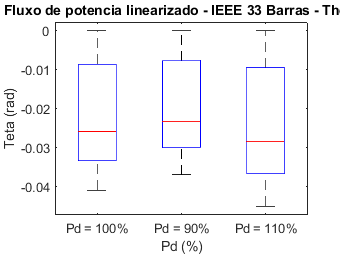


% Box Plot Teta
figure(3)
boxplot([Teta Teta1 Teta2],'Labels',{'Pd = 100%','Pd = 90%','Pd = 110%'})
title('Fluxo de potencia linearizado - IEEE 33 Barras - Theta')
ylabel('Teta (rad)')
xlabel('Pd (%)')

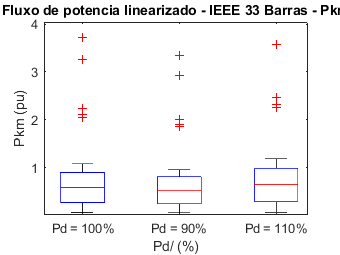



% Box Plot Pkm
figure(4)
boxplot([Pkm Pkm1 Pkm2],'Labels',{'Pd = 100%','Pd = 90%','Pd = 110%'})
title('Fluxo de potencia linearizado - IEEE 33 Barras - Pkm')
ylabel('Pkm (pu)')
xlabel('Pd/ (%)')